Data Set

ads = audioDatastore("D:\Tec\Clases\Analisis de señales y sistemas\Situacion Problema\cerebot\datos","IncludeSubfolders",true , ...
    "FileExtensions",".wav","LabelSource","foldernames");
[adsTrain,adsTest] = splitEachLabel(ads,0.8);
adsTrain

adsTrain =   audioDatastore with properties:

                       Files: {
                              ' ...\Situacion Problema\cerebot\datos\Adrian\adrian001.wav';
                              ' ...\Situacion Problema\cerebot\datos\Adrian\adrian002.wav';
                              ' ...\Situacion Problema\cerebot\datos\Adrian\adrian003.wav'
                               ... and 1141 more
                              }
                     Folders: {
                              ' ...\Analisis de señales y sistemas\Situacion Problema\cerebot\datos'
                              }
                      Labels: [Adrian; Adrian; Adrian ... and 1141 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


trainDatastoreCount = countEachLabel(adsTrain)

trainDatastoreCount = 13×2 table
     Label      Count
    ________    _____

    Adrian       88  
    Alfredo      88  
    Bruno        88  
    Daniel       88  
    Elias        88  
    Emiliano     88  
    Itzel        88  
    JP           88  
    Mariam       88  
    Oscar        88  
    Paola        88  
    Yestli       88  
    Yonathan     88  


adsTest

adsTest =   audioDatastore with properties:

                       Files: {
                              ' ...\Situacion Problema\cerebot\datos\Adrian\adrian089.wav';
                              ' ...\Situacion Problema\cerebot\datos\Adrian\adrian090.wav';
                              ' ...\Situacion Problema\cerebot\datos\Adrian\adrian091.wav'
                               ... and 283 more
                              }
                     Folders: {
                              ' ...\Analisis de señales y sistemas\Situacion Problema\cerebot\datos'
                              }
                      Labels: [Adrian; Adrian; Adrian ... and 283 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


testDatastoreCount = countEachLabel(adsTest)

testDatastoreCount = 13×2 table
     Label      Count
    ________    _____

    Adrian       22  
    Alfredo      22  
    Bruno        22  
    Daniel       22  
    Elias        22  
    Emiliano     22  
    Itzel        22  
    JP           22  
    Mariam       22  
    Oscar        22  
    Paola        22  
    Yestli       22  
    Yonathan     22  


[sampleTrain,dsInfo] = read(adsTrain);
sound(sampleTrain,dsInfo.SampleRate)
reset(adsTrain)

Feature Extraction

fs = dsInfo.SampleRate;
windowLength = round(0.03*fs);
overlapLength = round(0.025*fs);
afe = audioFeatureExtractor(SampleRate=fs, ...
    Window=hamming(windowLength,"periodic"),OverlapLength=overlapLength, ...
    zerocrossrate=true,shortTimeEnergy=true,pitch=true,mfcc=true);
featureMap = info(afe)

featureMap = struct with fields:
               mfcc: [1 2 3 4 5 6 7 8 9 10 11 12 13]
              pitch: 14
      zerocrossrate: 15
    shortTimeEnergy: 16


features = [];
labels = [];
energyThreshold = 0.01;
zcrThreshold = 0.3;

keepLen = round(length(sampleTrain)/3);

while hasdata(adsTrain)
    [audioIn,dsInfo] = read(adsTrain);

    % Take the first portion of each recording to speed up code
    audioIn = audioIn(1:keepLen);

    feat = extract(afe,audioIn);
    isSpeech = feat(:,featureMap.shortTimeEnergy) > energyThreshold;
    isVoiced = feat(:,featureMap.zerocrossrate) < zcrThreshold;

    voicedSpeech = isSpeech & isVoiced;

    feat(~voicedSpeech,:) = [];
    feat(:,[featureMap.zerocrossrate,featureMap.shortTimeEnergy]) = [];
    label = repelem(dsInfo.Label,size(feat,1));
    
    features = [features;feat];
    labels = [labels,label];
end
M = mean(features,1);
S = std(features,[],1);
features = (features-M)./S;

Training a Classifier

trainedClassifier = fitcknn(features,labels, ...
    Distance="euclidean", ...
    NumNeighbors=5, ...
    DistanceWeight="squaredinverse", ...
    Standardize=false, ...
    ClassNames=unique(labels));
k = 10;
group = labels;
c = cvpartition(group,KFold=k); % 5-fold stratified cross validation
partitionedModel = crossval(trainedClassifier,CVPartition=c);
validationAccuracy = 1 - kfoldLoss(partitionedModel,LossFun="ClassifError");
fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy*100);


Validation accuracy = 98.10%


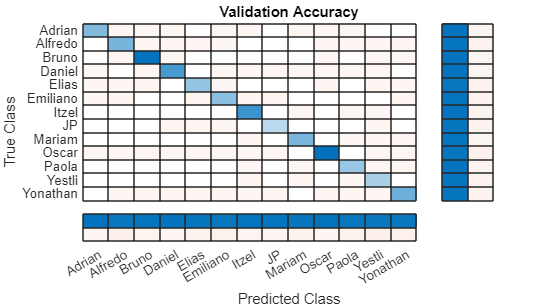

validationPredictions = kfoldPredict(partitionedModel);
figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(labels,validationPredictions,title="Validation Accuracy", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

Testing the Classifier

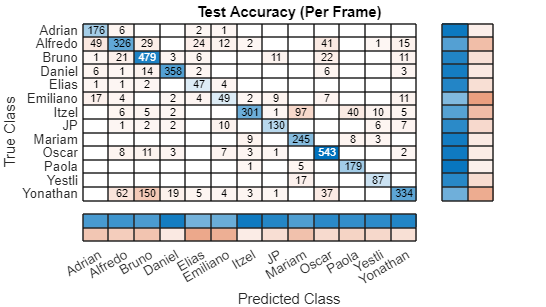

features = [];
labels = [];
numVectorsPerFile = [];
while hasdata(adsTest)
    [audioIn,dsInfo] = read(adsTest);
    
    % Take the same first portion of each recording to speed up code
    audioIn = audioIn(1:keepLen);

    feat = extract(afe,audioIn);

    isSpeech = feat(:,featureMap.shortTimeEnergy) > energyThreshold;
    isVoiced = feat(:,featureMap.zerocrossrate) < zcrThreshold;

    voicedSpeech = isSpeech & isVoiced;

    feat(~voicedSpeech,:) = [];
    numVec = size(feat,1);
    feat(:,[featureMap.zerocrossrate,featureMap.shortTimeEnergy]) = [];
    
    label = repelem(dsInfo.Label,numVec);
    
    numVectorsPerFile = [numVectorsPerFile,numVec];
    features = [features;feat];
    labels = [labels,label];
end
features = (features-M)./S;
prediction = predict(trainedClassifier,features);
prediction = categorical(string(prediction));
figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(labels(:),prediction,title="Test Accuracy (Per Frame)", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

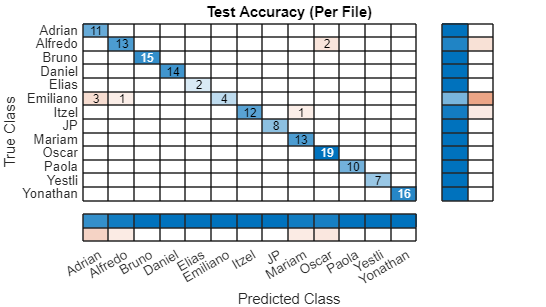

r2 = prediction(1:numel(adsTest.Files));
idx = 1;
for ii = 1:numel(adsTest.Files)
    r2(ii) = mode(prediction(idx:idx+numVectorsPerFile(ii)-1));
    idx = idx + numVectorsPerFile(ii);
end

figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(adsTest.Labels,r2,title="Test Accuracy (Per File)", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

Guardar variables

filenameMAT = 'energy.mat';
save(filenameMAT, 'energyThreshold');

filenameMAT = 'zeros.mat';
save(filenameMAT, 'zcrThreshold');

filenameMAT = 'modelo.mat';
save(filenameMAT, 'trainedClassifier');

filenameMAT = 'media.mat';
save(filenameMAT, 'M');

filenameMAT = 'estandar.mat';
save(filenameMAT, 'S');